y1a = out.waveformPeaks1a;
y1aIsNZ=(~y1a==0);  
x1a = out.bloodPressurePeaks1a;
x1aIsNZ=(~x1a==0);  
%p = polyfit(out.bloodPressurePeaks, out.waveformPeaks, 3)
x1a_1 = out.bloodPressurePeaks1a(x1aIsNZ);
y1a_1 = out.waveformPeaks1a(y1aIsNZ)

y1a_1 =     2.0054
    2.0054
    2.0054
    2.0054
    2.0054
    2.0054
    2.0054
    2.0054
    2.0054
    2.0054


p1a = polyfit(x1a_1, y1a_1, 2)

p1a =    -0.0258    4.7897 -204.1937


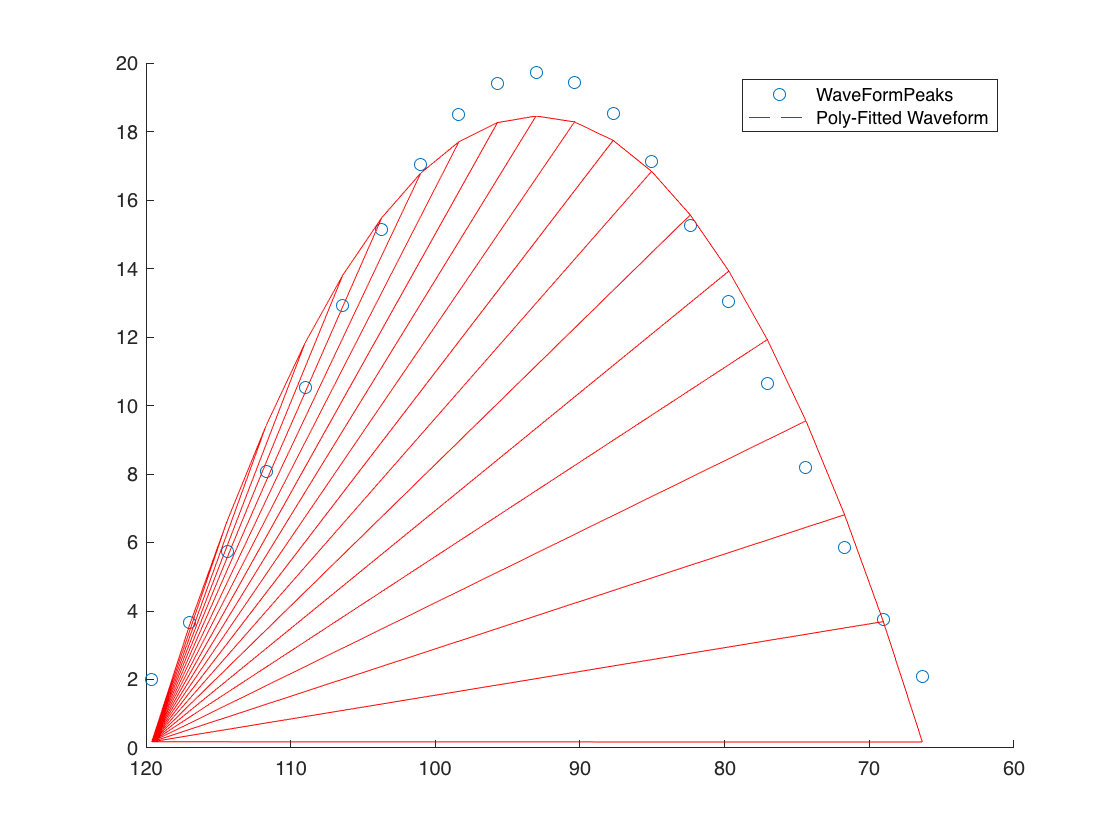

polyFittedWaveformY_1a = polyval(p1a,x1a_1);
figure
hold on
plot(x1a_1,y1a_1,'o')
set(gca, 'XDir','reverse')
plot(x1a_1,polyFittedWaveformY_1a,'r--')
legend('WaveFormPeaks','Poly-Fitted Waveform')

[M_1a,IndexOfMax_1a] = max(polyFittedWaveformY_1a)

M_1a = 18.4524

IndexOfMax_1a = 13749

systolic_1a = max(roots(p1a))

systolic_1a = 119.7320

MAP_1a= x1a_1(IndexOfMax_1a)

MAP_1a = 93.0400

diastolic_1a = (3/2)*(MAP_1a-(1/3)*systolic_1a)

diastolic_1a = 79.6940

y1b = out.waveformPeaks1b;
y1bIsNZ=(~y1b==0);  
x1b = out.bloodPressurePeaks1b;
x1bIsNZ=(~x1b==0);  
%p = polyfit(out.bloodPressurePeaks, out.waveformPeaks, 3)
x1b_1 = out.bloodPressurePeaks1b(x1bIsNZ);
y1b_1 = out.waveformPeaks1b(y1bIsNZ)

y1b_1 =     2.1672
    2.1672
    2.1672
    2.1672
    2.1672
    2.1672
    2.1672
    2.1672
    2.1672
    2.1672


p1b = polyfit(x1b_1, y1b_1, 2)

p1b =    -0.0260    4.8436 -206.5439


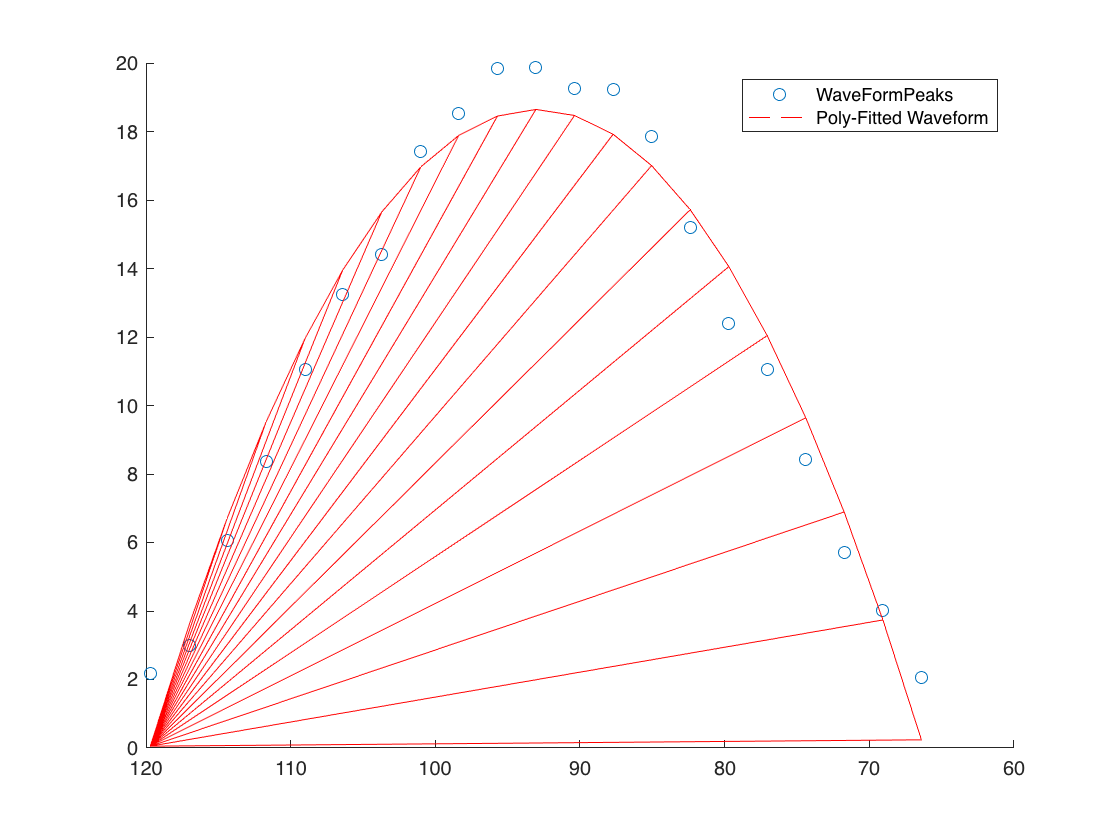

polyFittedWaveformY_1b = polyval(p1b,x1b_1);
figure
hold on
plot(x1b_1,y1b_1,'o')
set(gca, 'XDir','reverse')
plot(x1b_1,polyFittedWaveformY_1b,'r--')
legend('WaveFormPeaks','Poly-Fitted Waveform')

[M_1b,IndexOfMax_1b] = max(polyFittedWaveformY_1b)

M_1b = 18.6445

IndexOfMax_1b = 13751

systolic_1b = max(roots(p1b))

systolic_1b = 119.7382

MAP_1b= x1b_1(IndexOfMax_1b)

MAP_1b = 93.0500

diastolic_1b = (3/2)*(MAP_1b-(1/3)*systolic_1b)

diastolic_1b = 79.7059